## Frequency analysis 

Mathilde Marie Duville

**Notice:** please, run the codes for figures in the command window to output them with a correct scale for visualization

### General concepts

The power spectrum describes the characteristics of a time series in the frequency domain. Particularly, it captures the randomness that might be inherent in around the system. It represents the** power** as a function of **frequency** and tells us where the energy is distributed. 

There are two main categories of methods for power spectral estimation: parametric and non-parametric. 

A **non-parametric **power spectral estimation does not assume any model for the distribution of the data. In that case, the method is based on the** Discrete Fourier Transform (DFT) **of the autocorrelation sequence.

Parametric estimation technics are based on assuming that the data is distributed according to a particular model. For instance, we might assume that the data x[n] is the output of a *linear time-invariant system* with a frequency response in response to a white noise input sequence w[n]. In this case, the power spectrum of the output is the power spectrum of the input (the power of the white noise) multiplied by the magnitude squared of the frequency response of the *system*.

Generally for biological data, the **periodogram **is computed from a **non-parametric **approach. The DFT of the autocorrelation sequence of the signal is calculated, that is simply the magnitude squared of the DFT divided by the length of the data.

To be able to conduct spectral analysis the following need to be addressed:

o The observed data exhibit **stochasticity**. (We want to **estimate** the power spectrum given a set of data; the Fourier transform of a random signal is in general undefined).

o The observed data is of finite length. In practice, the finite length is equivalent to multiplying the data by a** window **of finite duration. Thus, the periodogram depends on a **normalization factor** that reflects the window properties. Windowing tend to introduce ***leakage*** of power across the neighbouring frequencies, given the wrong impression of stronger or weaker spectral components. When the window is **rectangular**, we call it a periodogram, otherwise, it is named a **modified periodogram** or window periodogram. 

As the window length increases, the mean value of the periodogram converges to the true value of the power spectrum. Therefore, asymptotically, as the number of **informative** samples increases, the estimator becomes unbiased. 

If the estimator is **asymptotically unbiased**, the variance may be also considered. The** variance **behaves like the square of the true power spectrum. It represents the variation of the data around its mean, and is independent of the number of samples (inconsistent). A good estimator tends to **lowest variance**. 

### **Discrete Fourier Transform (DFT)**

The DFT considers `N` equidistant samples in the interval `[0 2π]` (a period), with spacing `2π/N`. That is `k `frequencies `𝜔 `would be generated, following: `𝜔𝑘=2𝜋𝑘/𝑁, 𝑘=0,1,2,…𝑁−1. `

Let's consider a signal `x(n) `of duration `L`. The DFT considers `N` samples of the frequency response (Fourrier transform) of `x(n).`

clc; clear; close all;
% N is the number of samples of the DFT. 
% x is discrete the time series of L samples
% k are the index of frequencies on which the DFT is defined
% Wk are the frequencies on which the DFT is defined
% Xk is the DFT 

x = [1,0.5,0.2,0.6,1,0.5,0.7,0.9,0.3,0.7,0.8];
x = x-mean(x); % Correct for Direct Current offset

% x = (2.5-(-2)).*rand(100,1) +(-2);
% x = x-mean(x); % Correct for Direct Current offset

The DFT would be defined by the following: 

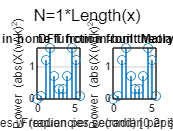

L = length(x); Wk = []; k = [];  Xk = []; N=length(x);
for k1 = 1:1:N 
    Wk1 = (2*pi*(k1-1))/N; 
% The first frequency is the Direct Current frequency (0; flat line; mean offest of the signal)
% If the mean of the signal is subtracted from the signal before
% computation of the DFT, the power at DC will be 0. To try it, just
% add "x = x-mean(x);" before the first loop.
    Wk = [Wk; Wk1]; k = [k; k1]; Xk2 = [];
    for n = 1:1:L
        Xk1 = []; Xk1 = x(n)*exp(-1i*2*pi*(k1-1)*(n-1)/N); Xk2 = [Xk2; Xk1];
    end
    Xk_sum = sum(Xk2);  Xk = [Xk; Xk_sum ];
end


% We can compare with the in-built Matlab function of the DFT
DFT= fft(x,N);

% Plots
figure('Windowstate', 'maximized')
subplot(1,2,1)
stem(Wk,abs(Xk).^2)
title('N-point power spectrum; N=L*20')
xlabel('Frequencies w (radian per second) [0 2pi]')
ylabel('Power (abs(X(w)k)^2)')
title('DFT from in-home function from theory')
xlim([0 max(Wk)]); ylim([0 max(abs(abs(Xk).^2))])
grid
subplot(1,2,2)
stem(Wk,abs(DFT).^2)
title('N-point power spectrum; N=L*20')
xlabel('Frequencies w (radian per second) [0 2pi]')
ylabel('Power (abs(X(w)k)^2)')
title('DFT from in-built Matlab function')
xlim([0 max(Wk)]); ylim([0 max(abs(DFT).^2)])
grid
sgtitle(['N=',num2str(length(DFT)/L), '*Length(x)'])

The** precision** (not resolution) of the DFT can be increased by increasing the number of DFT samples (`N`). That is, **uniformative** values (a series of 0) may be added to the signal. This method is calle zero-padding. For instance: 

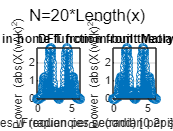

L = length(x); Wk = []; k = [];  Xk = []; N=L*20;
for k1 = 1:1:N
    Wk1 = (2*pi*(k1-1))/N;
% The first frequency is the Direct Current frequency (0; flat line; mean offest of the signal)
% If the mean of the signal is subtracted from the signal before
% computation of the DFT, the power at DC will be 0. To try it, just
% add "x = x-mean(x);" before the first loop.
    Wk = [Wk; Wk1]; k = [k; k1]; Xk2 = [];
    for n = 1:1:L
        Xk1 = []; Xk1 = x(n)*exp(-1i*2*pi*(k1-1)*(n-1)/N); Xk2 = [Xk2; Xk1];
    end
    Xk_sum = sum(Xk2);  Xk = [Xk; Xk_sum ];
end

% We can compare with the in-built Matlab function of the DFT
DFT= fft(x,N);

% Plots
figure('Windowstate', 'maximized')
subplot(1,2,1)
stem(Wk,abs(Xk).^2)
xlabel('Frequencies w (radian per second) [0 2pi]')
ylabel('Power (abs(X(w)k)^2)')
title('DFT from in-home function from theory')
xlim([0 max(Wk)]); ylim([0 max(abs(abs(Xk).^2))])
grid
subplot(1,2,2)
stem(Wk,abs(DFT).^2)
xlabel('Frequencies w (radian per second) [0 2pi]')
ylabel('Power (abs(X(w)k)^2)')
title('DFT from in-built Matlab function')
xlim([0 max(Wk)]); ylim([0 max(abs(DFT).^2)])
grid
sgtitle(['N=',num2str(length(DFT)/L), '*Length(x)'])

**To increase precision, more samples must be collected (by increasing the sampling rate or the duration of the recording).**

As can be observed in the code above, the Fourrier transform consists of computing the dot product between the time series and several** complex sine waves**, each of different frequency. That is, the frequency profile of the signal is "passed through" the spectral information of the sine wave (acts as a **filter** at the frequency of the sine wave), and the power (and phase) information may be measured. 

Each sine wave is defined by the following expression: `sin(2*pi*freq.*time)*amplitude`, to which may be added a phase offset parameter in range [-pi pi]; 

As you may have noticed in the graphic representations of the DFT, the power spectrum is "mirrored". This happens for real-valued time series. The first half of frequencies are "positive", and the second half are "negative". The negative frequencies may be ignored because they do not add any information to the power spectrum density of the positive ones. 

From this, the Nyquist theorem may be infered: at least 2 samples per cycle are needed to measure a sine wave. Therefore, **the DFT will always output half of the number of samples (as positive or negative frequencies) of the time series, plus the DC frequency. Therefore, (nb_samples/2) + 1 is the frequency resolution of the power spectrum.**

To express the frequencies in Hz, a vector of linearly and equally spaced values from 0 to the Nyquist frequency can be created. 

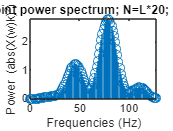

fs = 256; %sampling rate in Hz (number of samples per seconds in the time series)
nyquist_freq = fs/2; frequencies = linspace(0,nyquist_freq,N/2+1)';

% Plots
figure('Windowstate', 'maximized')
pwr = abs(Xk).^2;
stem(frequencies,pwr(1:N/2+1))
title('N-point power spectrum; N=L*20; Fs=256')
xlabel('Frequencies (Hz)')
ylabel('Power (abs(X(w)k)^2)')
xlim([0 nyquist_freq]); ylim([0 max(pwr)])

### **Welch's method**

The Fourrier transform assumes that the data is stationary, considering stable statistics of the data over time (e.g., mean, variance, spectral structures). However, as mentioned previously, biological data are usually stochastic. Thus, as biological data violate stationarity, the Fourrier transform may not be fully adequate.** The stochasticity of biological data would increase the variance of the periodogram so that the estimate of the power spectral density would not be accurate. **Temporally localized time decomposition may be more relevant as they assume stationnarity only on short periods of time, which may be reasonable for biological data. Please refer to the PDF and mlx document "*TimeFrequency*".

However, to extract the power spectral density (without the "time" dimensionality), the **Welch method** may be implemented. That is, when stochastic signals are averaged, the "noise" would decrease, reducing the variance of the signal.The goal of the Welch method is to decrease the variance of the power spectral density estimate. Therefore, the time series may be segmented into several overlaped time windows. The periodogram may be computed and averaged across time windows that compose the initial time series.

Here is an example of spectral decomposition of electroencephalographic data. 

*Start EEGLab (https://sccn.ucsd.edu/eeglab/index.php)*

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available

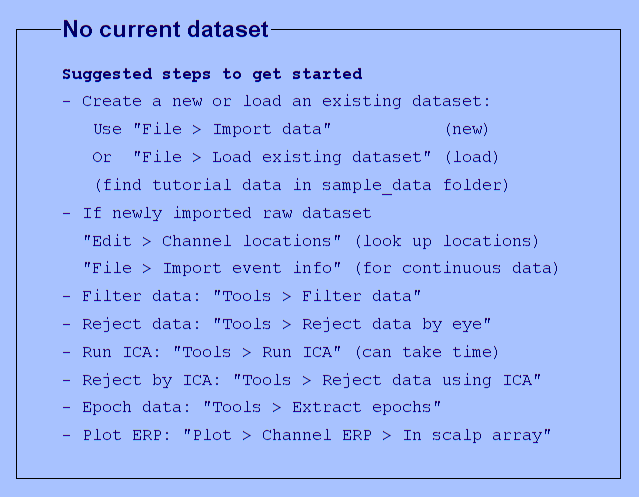

clear; clc; close all; 
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

*Import previously preprocessed data*

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Frequency\Part22-Human_Anger.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Frequency\Part22-Human_Anger.fdt'...


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


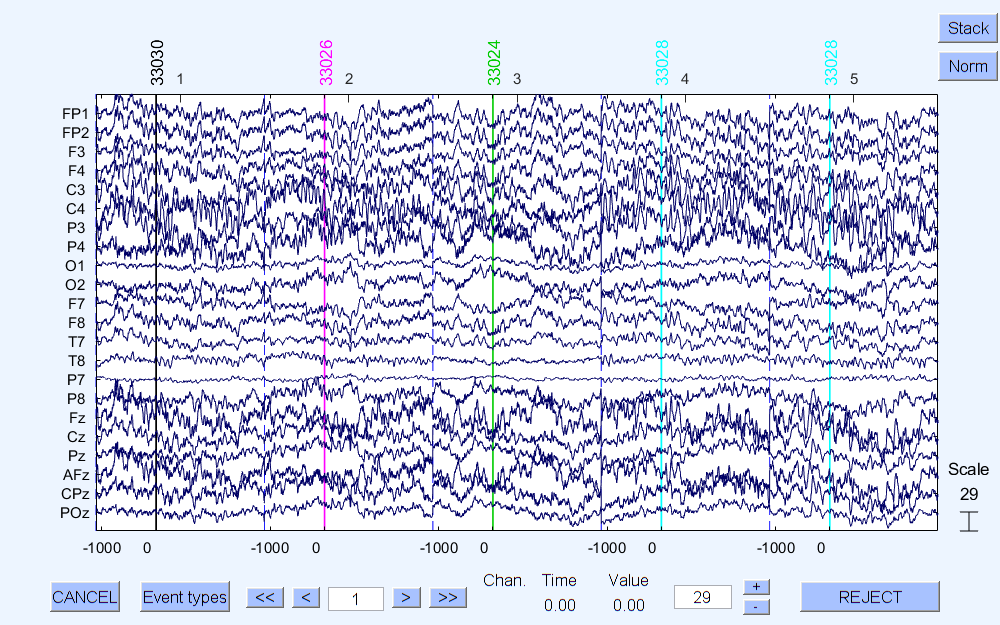

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Frequency\Part33-Human_Anger.set ...
Reading float file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\Frequency\Part33-Human_Anger.fdt'...


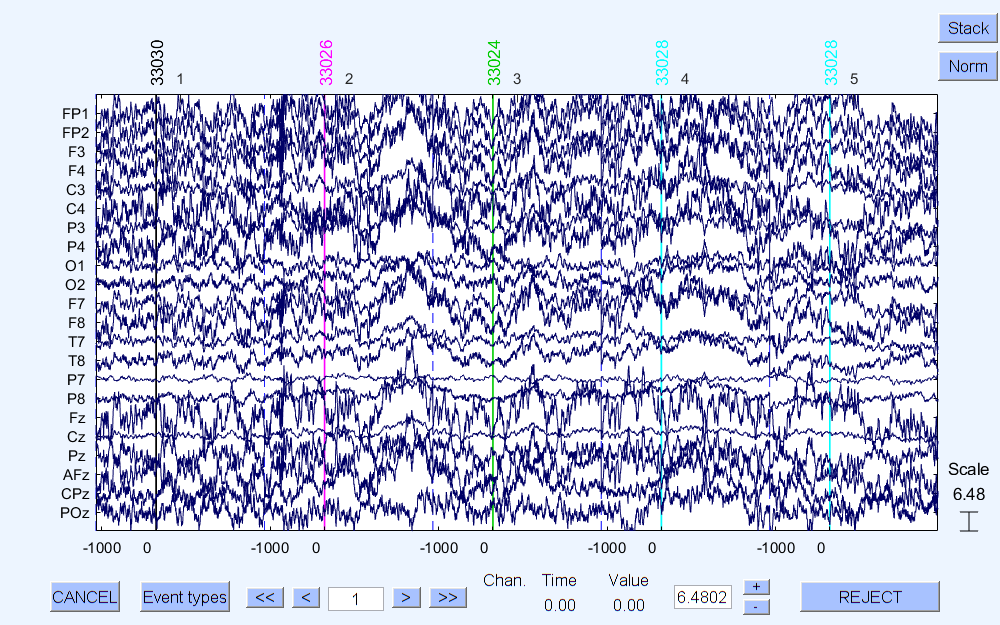

MainPath = pwd; folder = uigetdir(); 
fileList = dir(fullfile(folder, '*.set')); L=length(fileList); n = cell(1,L);
for i = 1:L
   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = name;
   EEG = []; EEG = pop_loadset('filename', fileList(i).name, 'filepath', MainPath);
   EEG.setname = fileList(i).name; CURRENTSET = []; CURRENTSET = i; 
   [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);
   % Visual chek-up of raw data 
   % Don't run in loop if too much files
   pop_eegplot(EEG, 1, 1, 1); 
end

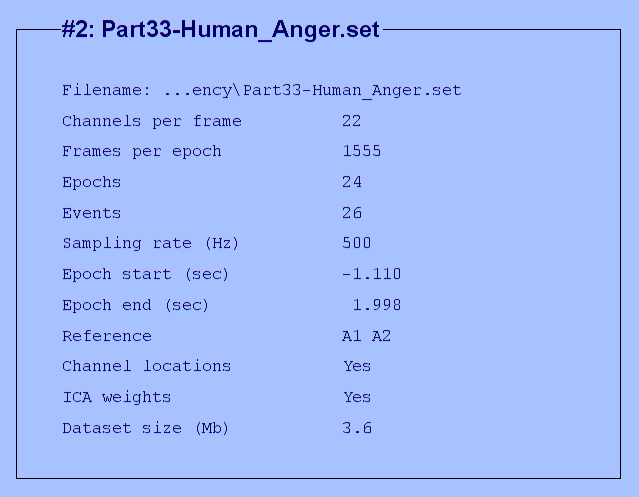

eeglab redraw

Periodogram (using a rectangle or blackman window: any type of window may be used, but it would induce different kind of spectral leakage. Therefore, the one that best suits your data should be chosen).

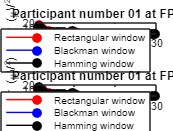

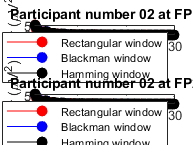

pxx_trial_rect= []; pxx_tr_avg_rect = []; pxx_trial_hamming= []; pxx_tr_avg_hamming = []; 
pxx_trial_blackman= []; pxx_tr_avg_blackman = []; 
for i = 1:1:size(ALLEEG,2) % Participants
    part= double(ALLEEG(i).data); fs= ALLEEG(i).srate;
    for j = 1:1:2%size(part, 1) %sensors - Here, only first two sensors to lower computation cost
        for k = 1:1:size(part,3) %Trials
            data = part(j,:,k); 
            N = 2^(round(log2(length(data)))); %Number of DFT samples

            window_rect = rectwin(length(data)); %rectangular window
            window_blackman = blackman(length(data)); %rectangular window
            window_hamming = hamming(length(data)); %hamming window
            
            pxx_rect = []; f = []; [pxx_rect,f] = periodogram(data,window_rect,N,fs);
            pxx_trial_rect(j,:,k,i) = pxx_rect; %sensors x time x trials x part

            pxx_blackman = []; f = []; [pxx_blackman,f] = periodogram(data,window_blackman,N,fs);
            pxx_trial_blackman(j,:,k,i) = pxx_blackman; %sensors x time x trials x part

            pxx_hamming = []; f = []; [pxx_hamming,f] = periodogram(data,window_hamming,N,fs);
            pxx_trial_hamming(j,:,k,i) = pxx_hamming; %sensors x time x trials x part
        end
    end
end

pxx_tr_avg_rect = squeeze(mean(pxx_trial_rect,3)); %sensors x time x part
pxx_tr_avg_blackman = squeeze(mean(pxx_trial_blackman,3)); %sensors x time x part
pxx_tr_avg_hamming = squeeze(mean(pxx_trial_hamming,3)); %sensors x time x part4

% Plot
labels = {EEG.chanlocs.labels}';
for i = 1:1:size(ALLEEG,2) %Participants
    figure('WindowState','maximized')
    for j = 1:1:size(pxx_tr_avg_blackman,1)
        subplot(2,1,j) %Adapt to number of sensors
        stem(f,pxx_tr_avg_rect(j,:,i),"filled", 'r');
        hold on
        stem(f,pxx_tr_avg_blackman(j,:,i), "filled", 'b');
        hold on
        stem(f,pxx_tr_avg_hamming(j,:,i), "filled", 'k');
        xlim([1 30])
        title(['Participant number ',  num2str(i,'%02.f'), ' at ', labels{j,1}])
        Lgnd = legend({'Rectangular window';'Blackman window';'Hamming window'});
        xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
    end
end

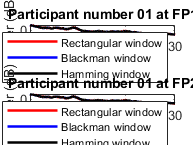

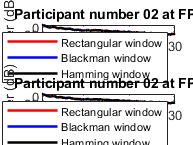


% Plot (in dB to attenuate the 1/f scaling of the power spectral density) 
for i = 1:1:size(ALLEEG,2) %Participants
    figure('WindowState','maximized')
    for j = 1:1:size(pxx_tr_avg_blackman,1)
        subplot(2,1,j) %Adapt to number of sensors
        plot(f,db(pxx_tr_avg_rect(j,:,i),'power'), "LineWidth", 1.5, "Color",'r');
        hold on
        plot(f,db(pxx_tr_avg_blackman(j,:,i),'power'), "LineWidth", 1.5, "Color",'b');
        hold on
        plot(f,db(pxx_tr_avg_hamming(j,:,i),'power'), "LineWidth", 1.5, "Color",'k');
        xlim([1 30])
        title(['Participant number ',  num2str(i,'%02.f'), ' at ', labels{j,1}])
        Lgnd = legend({'Rectangular window';'Blackman window';'Hamming window'});
        xlabel('Frequencies (Hz)'); ylabel('Power (dB)')
    end
end

Periodogram with Welch's method. In this example, the data is segmented into 8 segments with 50% overlap. As previously, different windows will be use to compare results. 

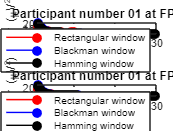

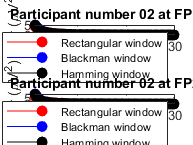

pxx_trial_rect= []; pxx_tr_avg_rect_pwelch = []; pxx_trial_blackman= []; pxx_tr_avg_blackman_pwelch = []; 
pxx_trial_hamming= []; pxx_tr_avg_hamming_pwelch = []; 

for i = 1:1:size(ALLEEG,2) % Participants
    part= double(ALLEEG(i).data); fs= ALLEEG(i).srate;
    for j = 1:1:2%size(part, 1) %sensors - Here, only first two sensors to lower computation cost
        for k = 1:1:size(part,3) %Trials
            data = part(j,:,k); 
            n = floor(length(data)/4.5); %number of samples for Welch's segments
            n_percent = 0.5; n_overlap = floor(n_percent*n); %50 % of window length
            N = 2^(round(log2(length(data)))); %Number of DFT samples            
            window_rect = rectwin(n); %rectangular window
            window_blackman = blackman(n); %rectangular window
            window_hamming = hamming(n); %rectangular window

            pxx_rect = []; f = []; [pxx_rect,f] = pwelch(data,window_rect,n_overlap,N,fs);
            pxx_trial_rect(j,:,k,i) = pxx_rect; %sensors x time x trials x part

            pxx_blackman = []; f = []; [pxx_blackman,f] = pwelch(data,window_blackman,n_overlap,N,fs);
            pxx_trial_blackman(j,:,k,i) = pxx_blackman; %sensors x time x trials x part

            pxx_hamming = []; f = []; [pxx_hamming,f] = pwelch(data,window_hamming,n_overlap,N,fs);
            pxx_trial_hamming(j,:,k,i) = pxx_hamming; %sensors x time x trials x part
        end
    end
end

pxx_tr_avg_rect_pwelch = squeeze(mean(pxx_trial_rect,3)); %sensors x time x part
pxx_tr_avg_blackman_pwelch = squeeze(mean(pxx_trial_blackman,3)); %sensors x time x part
pxx_tr_avg_hamming_pwelch = squeeze(mean(pxx_trial_hamming,3)); %sensors x time x part

% Plot
labels = {EEG.chanlocs.labels}';
for i = 1:1:size(ALLEEG,2) %Participants
    figure('WindowState','maximized')
    for j = 1:1:size(pxx_tr_avg_blackman_pwelch,1)
        subplot(2,1,j) %Adapt to number of sensors
        stem(f,pxx_tr_avg_rect_pwelch(j,:,i),"filled", 'r');
        hold on
        stem(f,pxx_tr_avg_blackman_pwelch(j,:,i), "filled", 'b');
        hold on
        stem(f,pxx_tr_avg_hamming_pwelch(j,:,i), "filled", 'k');
        xlim([1 30])
        title(['Participant number ',  num2str(i,'%02.f'), ' at ', labels{j,1}])
        Lgnd = legend({'Rectangular window';'Blackman window'; 'Hamming window'});
        xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
    end
end

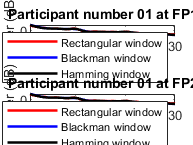

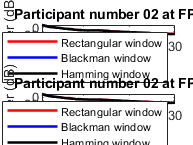


% Plot (in dB to attenuate the 1/f scaling of the power spectral density) 
for i = 1:1:size(ALLEEG,2) %Participants
    figure('WindowState','maximized')
    for j = 1:1:size(pxx_tr_avg_blackman_pwelch,1)
        subplot(2,1,j) %Adapt to number of sensors
        plot(f,db(pxx_tr_avg_rect_pwelch(j,:,i),'power'), "LineWidth", 1.5, "Color",'r');
        hold on
        plot(f,db(pxx_tr_avg_blackman_pwelch(j,:,i),'power'), "LineWidth", 1.5, "Color",'b');
        hold on
        plot(f,db(pxx_tr_avg_hamming_pwelch(j,:,i),'power'), "LineWidth", 1.5, "Color",'k');
        xlim([1 30])
        title(['Participant number ',  num2str(i,'%02.f'), ' at ', labels{j,1}])
        Lgnd = legend({'Rectangular window';'Blackman window'; 'Hamming window'});
        xlabel('Frequencies (Hz)'); ylabel('Power (dB)')
    end
end

Summary plot

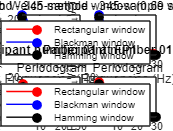

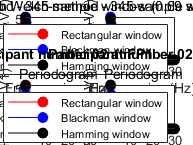

for i = 1:1:size(ALLEEG,2) %Participants
    figure('WindowState','maximized')
    for j = 1:1:size(pxx_tr_avg_blackman_pwelch,1)
        subplot(2,2,j) %Adapt to number of sensors
        stem(f,pxx_tr_avg_rect_pwelch(j,:,i),"filled", 'r');
        hold on
        stem(f,pxx_tr_avg_blackman_pwelch(j,:,i), "filled", 'b');
        hold on
        stem(f,pxx_tr_avg_hamming_pwelch(j,:,i), "filled", 'k');
        xlim([1 30])
        title(['Participant number ',  num2str(i,'%02.f'), ' at ', labels{j,1}])
        subtitle(['Periodogram with Welch method - ', num2str(n,'%02.f'), '-sample window (',...
            num2str(1/(fs/n)), ' sec) - ' , num2str(n_percent*100), '% overlap'])
        Lgnd = legend({'Rectangular window';'Blackman window'; 'Hamming window'});
        xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
    end
    j = []; 
    for j = 1:1:size(pxx_tr_avg_blackman,1)
        subplot(2,2,(j+size(pxx_tr_avg_blackman_pwelch,1))) %Adapt to number of sensors
        stem(f,pxx_tr_avg_rect(j,:,i),"filled", 'r');
        hold on
        stem(f,pxx_tr_avg_blackman(j,:,i), "filled", 'b');
        hold on
        stem(f,pxx_tr_avg_hamming(j,:,i), "filled", 'k');
        xlim([1 30])
        title(['Participant number ',  num2str(i,'%02.f'), ' at ', labels{j,1}])
        subtitle('Periodogram');
        Lgnd = legend({'Rectangular window';'Blackman window';'Hamming window'});
        xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
    end
end

Here, the frequency analysis is extended to speech signals for:

- Mel Frequency Cepstral Coefficient extraction (MFCC)

- Extraction of the intensity of the 1st (fundamental frequency F0), 2nd, 3rd,and 4th harmonics (H1, H2, H3, and H4) 

- Correction of intensities for formant bias, according to the formula correction proposed by Iseli and Alwan (2004) 

- Multiband parametric equalization to reduce the intensity of harmonics 1 and 4.

## Mel Frequency Cepstral Coefficient extraction (MFCC)

Please see the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

The audio file is a recording of a child uttering the Spanish word "Fantástico" with a happy prosody.

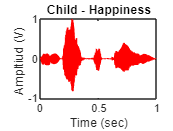

clc; clear; close all; 
[data,fs] = audioread('Child_happiness.wav');
player = audioplayer(data, fs); 
play(player) % play speech 

time=[0:length(data)-1]/fs;
figure('WindowState','maximized')
plot(time, data, LineWidth=0.2, Color='r');
title("Child - Happiness"); ylabel("Ampltiud (V) "); xlabel("Time (sec)")

*Extract coefficients*

A 20-ms window segmentation with 10-ms overlap will be defined for windowing the time series (hamming window).

*Window:*

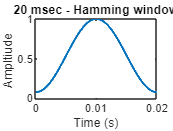

window = hamming(round(fs*0.02),'periodic');
time_window = [0:length(window)-1]/fs;
plot(time_window, window, LineWidth=1.5);
title("20 msec - Hamming window")
ylabel("Ampltiude "); xlabel("Time (s)")

13 coefficients will be represented per window.

-  "coeffs"  will contain the logEnergy followed by the 13 MFCC.

- "delta" are the 1st derivative of the coefficients

- "deltaDelta" are the 2nd derivative of the coefficients

- "loc" contains the location of last sample in every analysis window

overlap = fs*0.01; % 10-ms overlap

[coeffs,delta,deltaDelta, loc] = mfcc(data,fs,...
    'WindowLength', length(window), 'OverlapLength',overlap, "NumCoeffs",13, ...
    'DeltaWindowLength',13, 'LogEnergy','Append');

### **Using cepstralFeatureExtractor**

clc; clear; close all; 
[data,fs] = audioread('Child_happiness.wav');
player = audioplayer(data, fs); 
play(player) % play speech 

time=[0:length(data)-1]/fs;
figure('WindowState','maximized')
plot(time, data, LineWidth=0.2, Color='r');
title("Child - Happiness"); ylabel("Ampltiud (V) "); xlabel("Time (sec)")

*Create the system object*

System object are designed to implement and simulate dynamic systems with time-variant inputs. It is a dynamic system whereing output values are dependent on both instant imput values and previous system behavior.

cepFeatures = cepstralFeatureExtractor('FilterBank', 'Mel', ...
   'NumCoeffs', 13,'LogEnergy', "Append", "SampleRate", fs, ...
   'FilterBankDesignDomain', 'Hz', 'FFTLength', []) ;

*Extract coefficients*

[coeffs,delta,deltaDelta] = cepFeatures(data);

*Plot the Mel filterbank*

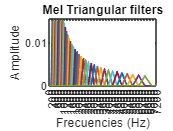

[filterbank,freq] = getFilters(cepFeatures);
figure('WindowState','maximized')
plot(freq, filterbank, 'LineWidth',1.2)
title('Mel Triangular filters'); ylabel('Amplitude'); xlabel('Frecuencies (Hz)');
xticks(0:200:max(freq));
xlim([0 7200]); ylim([0 max(max(filterbank))+0.0005])

### Using " melSpectrogram" to plot the spectogram in the Mel scale

"MelSpect" is the Mel Frequency spectrum of the time series. Rows represent the triangular filters; colums are the segments of windowing of the time series. 

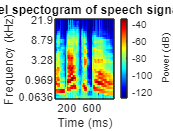

[MelSpect,FreqCent,LocFreqCent] = melSpectrogram(data,fs, 'NumBands', size(filterbank,2));
figure('WindowState','normal')
melSpectrogram(data,fs, 'NumBands', size(filterbank,2));
set(gca, "Colormap", jet(230));
title('Mel spectogram of speech signal');

## Extraction of the intensity of the 1st (fundamental frequency F0), 2nd, 3rd,and 4th harmonics (H1, H2, H3, and H4) 

clc; clear; close all; 
[data,fs] = audioread('Child_happiness.wav');
% player = audioplayer(data, fs); 
% play(player) % play speech 

time=[0:length(data)-1]/fs;
figure('WindowState','maximized')
plot(time, data, LineWidth=0.2, Color='r');
title("Child - Happiness"); ylabel("Ampltiud (V) "); xlabel("Time (sec)")

Plot the Power Spectral Density 

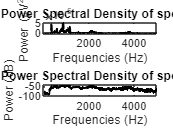

n = floor(length(data)/4.5); %number of samples for Welch's segments
n_percent = 0.5; n_overlap = floor(n_percent*n); %50 % of window length
N = 2^(round(log2(length(data)))); %Number of DFT samples            
window_hamming = hamming(n); %rectangular window
[pxx_hamming,f] = pwelch(data,window_hamming,n_overlap,N,fs);
figure('WindowState','maximized')
subplot(2,1,1)
plot(f,pxx_hamming, 'LineWidth',1.5,'Color','k');
xlim([1 5000])
title('Power Spectral Density of speech')
xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
subplot(2,1,2)
plot(f,db(pxx_hamming,'power'), 'LineWidth',1.5, 'Color','k');
xlim([1 5000])
title('Power Spectral Density of speech')
xlabel('Frequencies (Hz)'); ylabel('Power (dB)')

Find local maxima's value, location and width

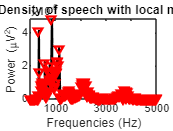

[pks,locs,width] = findpeaks(pxx_hamming, f); 

%plot 
figure('WindowState','maximized')
plot(f,pxx_hamming, 'LineWidth',1.5,'Color','k');
hold on;
plot(locs, pks, 'rv', 'LineWidth', 1.5, 'MarkerSize', 5);
xlim([1 5000])
title('Power Spectral Density of speech with local maxima highlighted')
xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')

Read value of median pitch computed previously with *Praat*. Please, refer to the *Praat* code available for pitch information extracion and to the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

F0 = readtable('01_duration_pitch.csv'); F0 = table2array(F0(:,2));

H2 = F0*2; % 2nd harmonic
H3 = F0*3; % 3rd harmonic
H4 = F0*4; % 4th harmonic

% F0
% Find harmonics within the frequency vector
F0_f = knnsearch(f, F0); H3_f = knnsearch(f,H3); H4_f = knnsearch(f,H4);
% f_F0 = f(F0_f); f_H3 = f(H3_f); f_H4 = f(H4_f);

% Create a frequency window to look for the maximum peak around the
% frequency of the harmonic 
f_step = f(2)-f(1); % linear
nb_samples = round(((F0/2)/f_step)/2); 
window = f(F0_f-nb_samples:F0_f+nb_samples); %window to search for the maximum peak

% Find frequencies of peaks that are part of the window
F0_window_freq = locs(knnsearch(locs,window));

% Find intensities of peaks that are part of the window
F0_window_int = pks(knnsearch(locs,window));

% Find widths of peaks that are part of the window
F0_window_width = width(knnsearch(locs,window));

% H2
% Find harmonics within the frequency vector
H2_f = knnsearch(f, H2); H3_f = knnsearch(f,H3); H4_f = knnsearch(f,H4);
% f_H2 = f(H2_f); f_H3 = f(H3_f); f_H4 = f(H4_f);

window = f(H2_f-nb_samples:H2_f+nb_samples); %window to search for the maximum peak

% Find frequencies of peaks that are part of the window
H2_window_freq = locs(knnsearch(locs,window));

% Find intensities of peaks that are part of the window
H2_window_int = pks(knnsearch(locs,window));

% Find widths of peaks that are part of the window
H2_window_width = width(knnsearch(locs,window));

% H3
% Find harmonics within the frequency vector
H3_f = knnsearch(f, H3); H3_f = knnsearch(f,H3); H4_f = knnsearch(f,H4);
% f_H3 = f(H3_f); f_H3 = f(H3_f); f_H4 = f(H4_f);

window = f(H3_f-nb_samples:H3_f+nb_samples); %window to search for the maximum peak

% Find frequencies of peaks that are part of the window
H3_window_freq = locs(knnsearch(locs,window));

% Find intensities of peaks that are part of the window
H3_window_int = pks(knnsearch(locs,window));

% Find widths of peaks that are part of the window
H3_window_width = width(knnsearch(locs,window));

% H4
% Find harmonics within the frequency vector
H4_f = knnsearch(f, H4); H4_f = knnsearch(f,H4); H4_f = knnsearch(f,H4);
% f_H4 = f(H4_f); f_H4 = f(H4_f); f_H4 = f(H4_f);

window = f(H4_f-nb_samples:H4_f+nb_samples); %window to search for the maximum peak

% Find frequencies of peaks that are part of the window
H4_window_freq = locs(knnsearch(locs,window));

% Find intensities of peaks that are part of the window
H4_window_int = pks(knnsearch(locs,window));

% Find widths of peaks that are part of the window
H4_window_width = width(knnsearch(locs,window));

Find maximum 

%F0
loc_max_int_F0 = knnsearch(F0_window_int,max(F0_window_int));
freq_F0 = F0_window_freq(loc_max_int_F0);
int_F0 = F0_window_int(loc_max_int_F0);
width_F0 = F0_window_width(loc_max_int_F0);

%H2
loc_max_int_H2 = knnsearch(H2_window_int,max(H2_window_int));
freq_H2 = H2_window_freq(loc_max_int_H2);
int_H2 = H2_window_int(loc_max_int_H2);
width_H2 = H2_window_width(loc_max_int_H2);

%H3
loc_max_int_H3 = knnsearch(H3_window_int,max(H3_window_int));
freq_H3 = H3_window_freq(loc_max_int_H3);
int_H3 = H3_window_int(loc_max_int_H3);
width_H3 = H3_window_width(loc_max_int_H3);

%H4
loc_max_int_H4 = knnsearch(H4_window_int,max(H4_window_int));
freq_H4 = H4_window_freq(loc_max_int_H4);
int_H4 = H4_window_int(loc_max_int_H4);
width_H4 = H4_window_width(loc_max_int_H4);

Save data in a table

freq_int_width = [F0, freq_F0, int_F0, width_F0,...
    H2, freq_H2, int_H2, width_H2, H3, freq_H3, int_H3, width_H3,...
    H4, freq_H4, int_H4, width_H4];

freq_int_width = array2table(freq_int_width, ...
    'VariableNames',{'F0','Freq_F0_peak','Intensity_F0','BW_F0',...
    'H2','Freq_H2_peak','Intensity_H2','BW_H2',...
    'H3','Freq_H3_peak','Intensity_H3','BW_H3',...
    'H4','Freq_H4_peak','Intensity_H4','BW_H4'});

freq_int_width

freq_int_width = 1×16 table
      F0      Freq_F0_peak    Intensity_F0    BW_F0      H2      Freq_H2_peak    Intensity_H2    BW_H2       H3      Freq_H3_peak    Intensity_H3    BW_H3       H4      Freq_H4_peak    Intensity_H4    BW_H4 
    ______    ____________    ____________    ______    _____    ____________    ____________    ______    ______    ____________    ____________    ______    ______    ____________    ____________    ______

    334.85 

### Correction of harmonics' intensities (in dB) for formant bias, according to the formula correction proposed by Iseli and Alwan (2004). 

Here, F0, H2, H3, and H4 are corrected for the effect of formants 1 and 2.

Iseli, M., & Alwan, A. (2004). An improved correction formula for the estimation of harmonic magnitudes and its application to open quotient estimation. *2004 IEEE International Conference on Acoustics, Speech, and Signal Processing*, *1*, I-669–672. [https://doi.org/10.1109/ICASSP.2004.1326074](https://doi.org/10.1109/ICASSP.2004.1326074)

Here, formants frequencies and bandwidths have been computed with *Praat*. Please, refer to the *Praat* code available for formant information extracion and to the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

Formants_all = readtable('02_F1-5-B1-5.csv');
F1_F2 = table2array(Formants_all(:,[2,3,7,8]));

%F0*
int_F0_dB = 10*log10(int_F0);
F0corr = func_correct_iseli_z_mathilde_2(int_F0_dB,...
    freq_F0, F1_F2(1), F1_F2(3), F1_F2(2), F1_F2(4), fs);

%H2*
int_H2_dB = 10*log10(int_H2);
H2corr = func_correct_iseli_z_mathilde_2(int_H2_dB,...
    freq_H2, F1_F2(1), F1_F2(3), F1_F2(2), F1_F2(4), fs);

%H3*
int_H3_dB = 10*log10(int_H3);
H3corr = func_correct_iseli_z_mathilde_2(int_H3_dB,...
    freq_H3, F1_F2(1), F1_F2(3), F1_F2(2), F1_F2(4), fs);

%H4*
int_H4_dB = 10*log10(int_H4);
H4corr = func_correct_iseli_z_mathilde_2(int_H4_dB,...
    freq_H4, F1_F2(1), F1_F2(3), F1_F2(2), F1_F2(4), fs);

Save data in table 

freq_int_width_corr = [freq_F0, int_F0, int_F0_dB, F0corr,...
    freq_H2, int_H2, int_H2_dB, H2corr, freq_H3, int_H3, int_H3_dB, H3corr,...
    freq_H4, int_H4, int_H4_dB, H4corr,];

freq_int_width_corr = array2table(freq_int_width_corr, ...
    'VariableNames',{'Freq_F0_peak','Intensity_F0','Intensity_F0_dB', 'Corrected_intensity_F0_dB',...
    'Freq_H2_peak','Intensity_H2','Intensity_H2_dB','Corrected_intensity_H2_dB',...
    'Freq_H3_peak','Intensity_H3','Intensity_H3_dB','Corrected_intensity_H3_dB',...
    'Freq_H4_peak','Intensity_H4','Intensity_H4_dB','Corrected_intensity_H4_dB'});

freq_int_width_corr

freq_int_width_corr = 1×16 table
    Freq_F0_peak    Intensity_F0    Intensity_F0_dB    Corrected_intensity_F0_dB    Freq_H2_peak    Intensity_H2    Intensity_H2_dB    Corrected_intensity_H2_dB    Freq_H3_peak    Intensity_H3    Intensity_H3_dB    Corrected_intensity_H3_dB    Freq_H4_peak    Intensity_H4    Intensity_H4_dB    Corrected_intensity_H4_dB
    ____________    ____________    _______________    _________________________    ____________    ____________    _______________    _________________________    ____________    ____________    

### Multiband parametric equalization to reduce the intensity of harmonics 1 and 4.

Please see the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

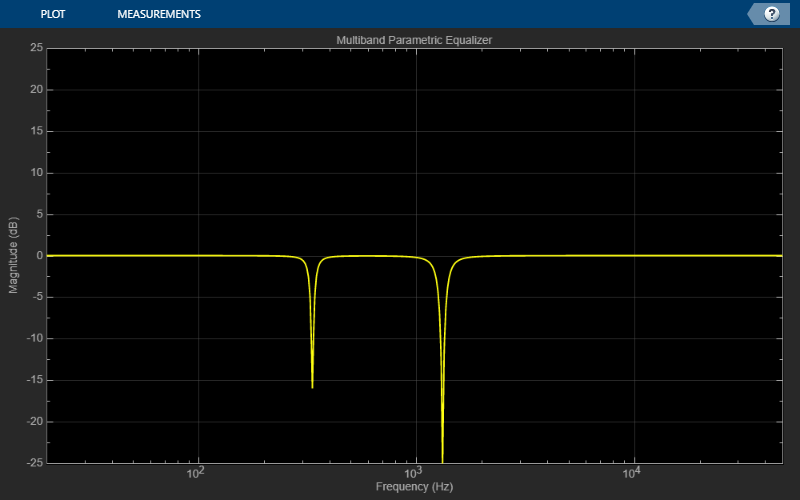

% Define gains (in dB)
freq_F0_gain = -15.99; 
freq_H4_gain = -25.12; 

% Quality factor F0
QA_F0 = freq_F0/width_F0;

% Quality factor H4
QA_H4 = freq_H4/width_H4;

mPEQ1 = multibandParametricEQ( ...
    'NumEQBands',2, ...
    'Frequencies',[freq_F0,freq_H4],...
    'PeakGains',[freq_F0_gain,freq_H4_gain],...
    'QualityFactors', [QA_F0,QA_H4],...
    'SampleRate', fs, ...
    'Oversample',true);

% plot equalizer
visualize(mPEQ1)


% Apply to speech signal 
data_EQ1 = mPEQ1(data);

Plot power spectral density before and after EQ

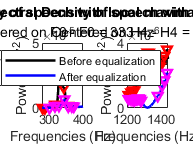

n = floor(length(data_EQ1)/4.5); %number of samples for Welch's segments
n_percent = 0.5; n_overlap = floor(n_percent*n); %50 % of window length
N = 2^(round(log2(length(data_EQ1)))); %Number of DFT samples            
window_hamming = hamming(n); %rectangular window
[pxx_hamming_EQ1,f_EQ1] = pwelch(data_EQ1,window_hamming,n_overlap,N,fs);
[pks_EQ1,locs_EQ1,width_EQ1] = findpeaks(pxx_hamming_EQ1, f_EQ1); 

% Centered on F0
figure('WindowState','maximized')
subplot(1,2,1)
p1 = plot(f,pxx_hamming, 'LineWidth',1.5,'Color','k');
hold on;
plot(locs, pks, 'rv', 'LineWidth', 1.5, 'MarkerSize', 5);
xlim([280 400])
title('Power Spectral Density of speech with local maxima highlighted')
subtitle(['Centered on F0 - F0 = ', num2str(freq_F0,'%02.f'), ' Hz'])
xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
hold on 
p2 = plot(f_EQ1,pxx_hamming_EQ1, 'LineWidth',1.5,'Color','b');
hold on;
plot(locs_EQ1, pks_EQ1, 'mv', 'LineWidth', 1.5, 'MarkerSize', 5);
xlim([280 400])
legend('show', [p1; p2], {'Before equalization', 'After equalization'});

% Centered on H4 1.3198e+03
subplot(1,2,2) 
p1 = plot(f,pxx_hamming, 'LineWidth',1.5,'Color','k');
hold on;
plot(locs, pks, 'rv', 'LineWidth', 1.5, 'MarkerSize', 5);
xlim([1200 1440])
title('Power Spectral Density of speech with local maxima highlighted')
subtitle(['Centered on H4 - H4 = ', num2str(freq_H4,'%02.f'), ' Hz'])
xlabel('Frequencies (Hz)'); ylabel('Power (\muV^2)')
hold on 
p2 = plot(f_EQ1,pxx_hamming_EQ1, 'LineWidth',1.5,'Color','b');
hold on;
plot(locs_EQ1, pks_EQ1, 'mv', 'LineWidth', 1.5, 'MarkerSize', 5);
xlim([1200 1440])
legend('show', [p1; p2], {'Before equalization', 'After equalization'});